### (Just to see how Adaptive Quadrature works visually with Runge function.)

Function

f=@(x) 1 ./ (1 + 25 .* x .^ 2)

f = 値をもつ function_handle :
    @(x)1./(1+25.*x.^2)


To integrate function from 0 to 0.8

a = -1;
b = 1;
p = [400 -900 675 -200 25 0.2];
q = polyint(p) % integrate polynomial equation (gives us the EXACT integration)

q =    66.6667 -180.0000  168.7500  -66.6667   12.5000    0.2000         0


Itrue = diff(polyval(q, [a, b])) % for relative value

Itrue = -492.9333

Plot original function along with simpson 1/3 rule with ns calculated from adaptive quadrature

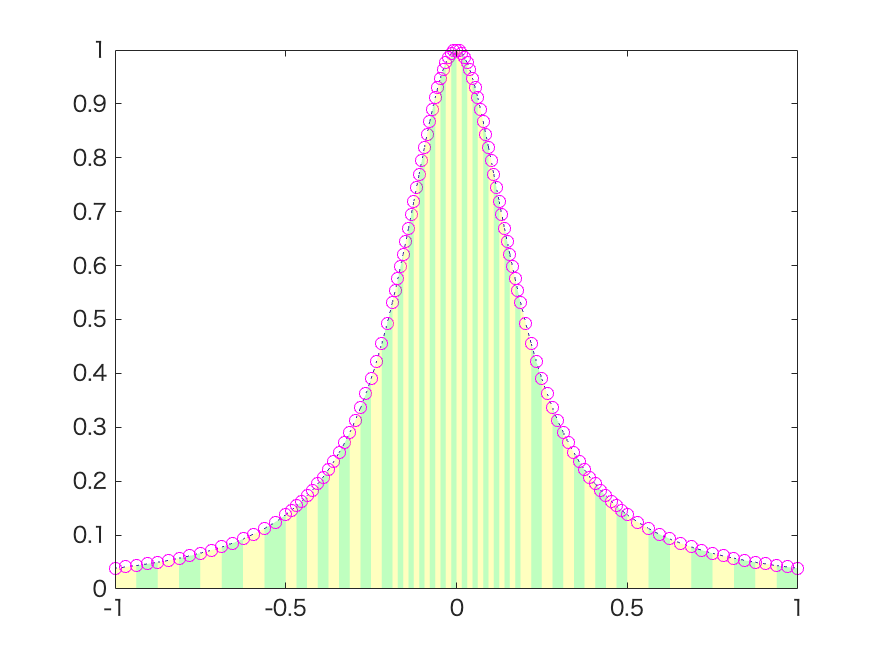

[I_quadadapt, xpts] = quadadaptWithPoints(f, a, b);

% show I_quadadapt
I_quadadapt;

% get y points
ypts = f(xpts);
% verify results
[xpts, ypts];

ns = (length(xpts) - 1) / 2;

figure
color = ['g', 'y'];
for i = 1:ns
    ileft = 2*(i-1)+1;
    iright = 2*i+1;
    newx = xpts(ileft:iright);
    newy = ypts(ileft:iright);
    p2 = polyfit(newx, newy, 2); % we;re trying to do quadratic fitting
    xx2 = linspace(xpts(ileft), xpts(iright));
    yy2 = polyval(p2, xx2);
    area(xx2, yy2, 'FaceColor',color(mod(i,2)+1),'FaceAlpha',0.25,'EdgeColor','flat','LineStyle',':')
    hold on
    plot(newx, newy, 'mo')
    % hold on
end